**Exercise 2 **

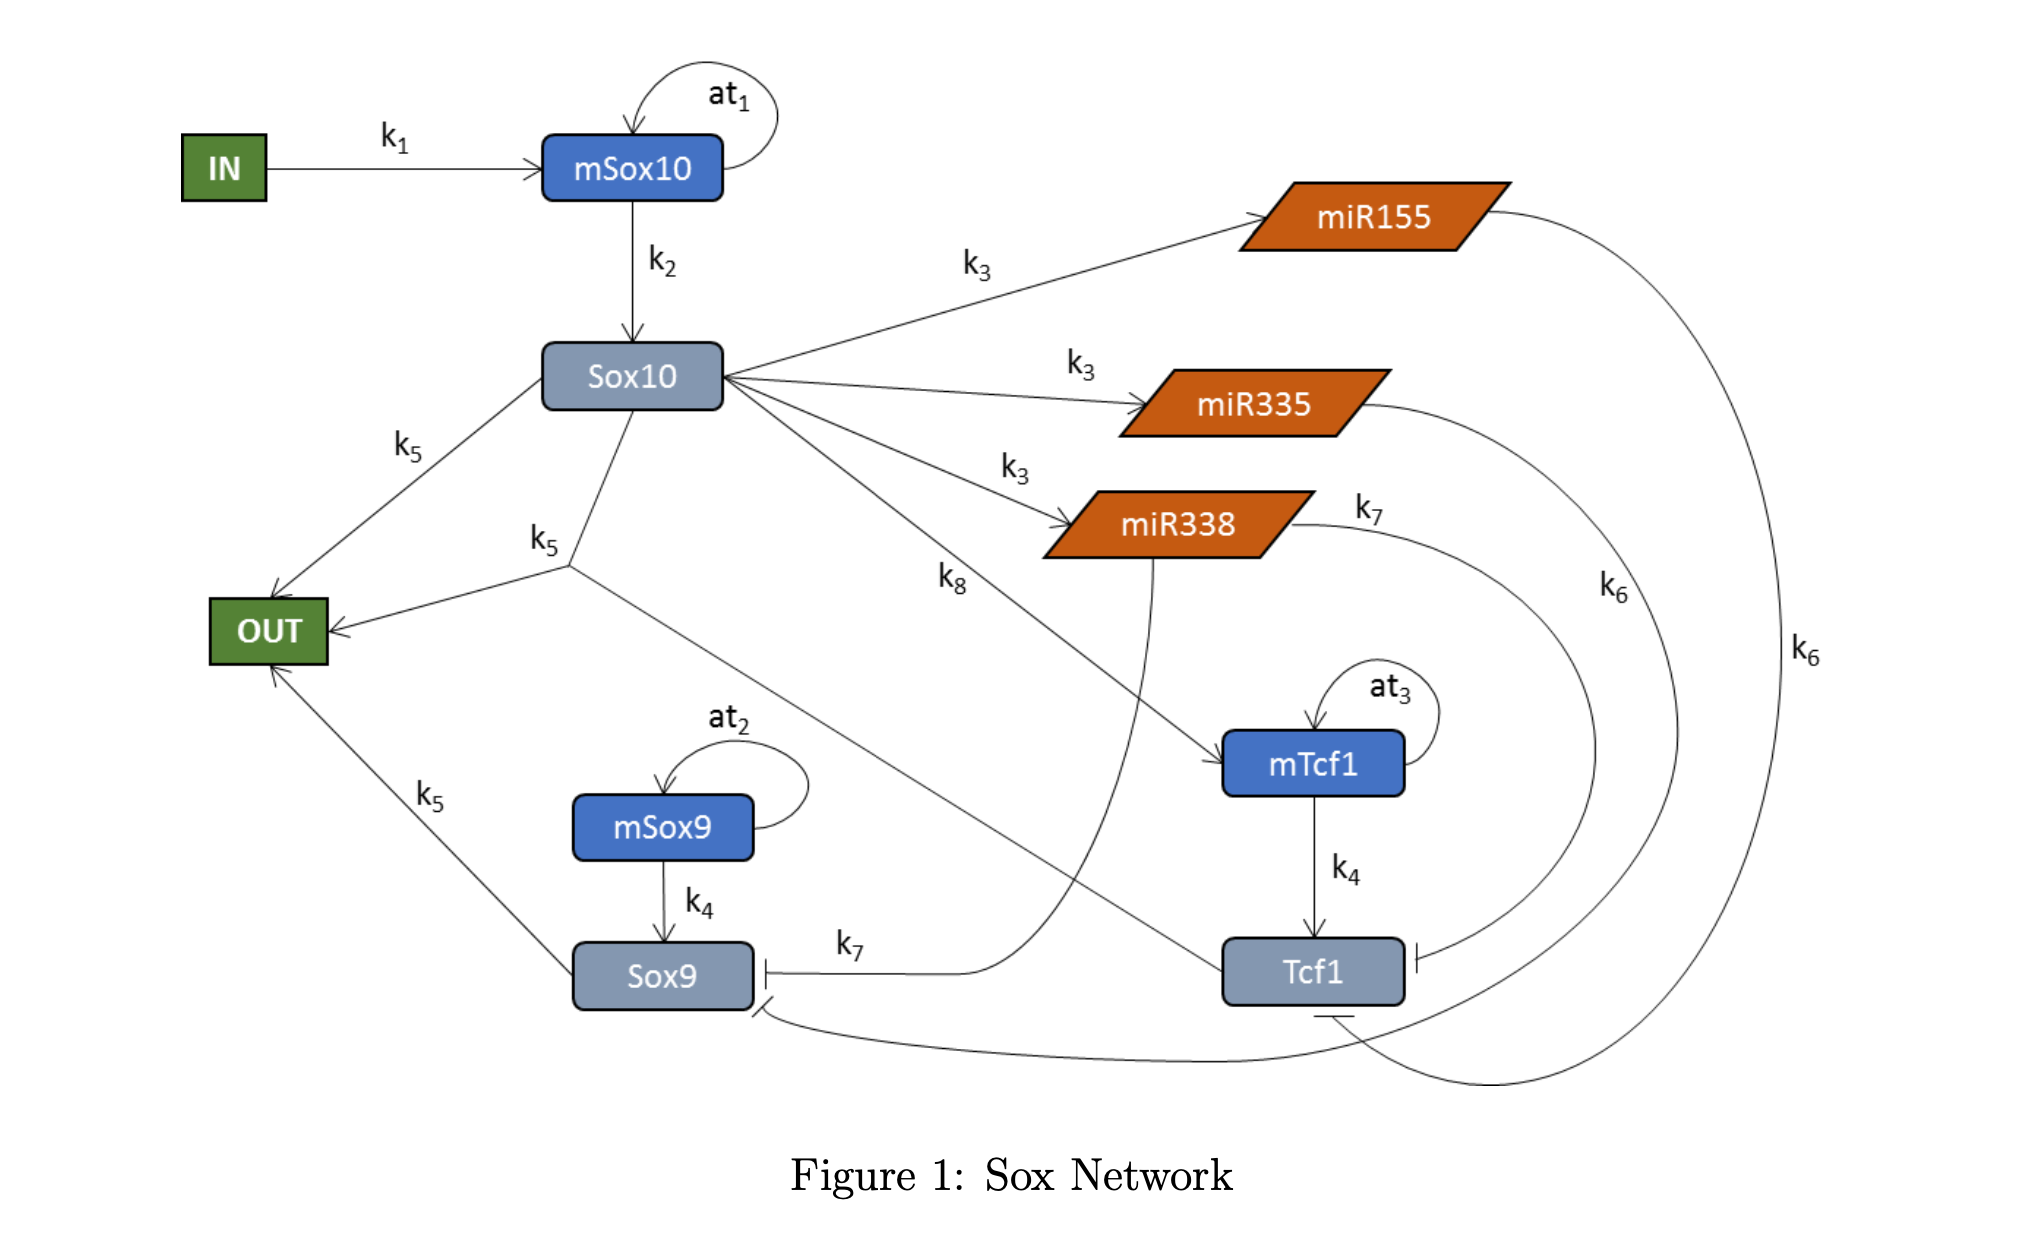

The parameter values of the network are:

k = [
    1;      % k1
    0.7;    % k2
    0.2;    % k3
    0.25;   % k4
    0.3;    % k5
    0.3;    % k6
    0.35;   % k7
    0.4     % k8
];

at = [
    0.7;    % at1
    0.25;   % at2
    0.3     % at3
];


y0 = [
    0.5; % 1) mSox10
    0;   % 2) Sox10
    1;   % 3) mSox9
    0;   % 4) Sox9
    0;   % 5) mTcf1
    0;   % 6) Tcf1
    0;   % 7) miR155
    0;   % 8) miR335
    0;   % 9) miR338
    0;   % 10) OUT (output)
];

time = 0:0.01:10;

• Negative feedback interactions (denoted by a vertical line with a horizontal end) appear as a negative (minus) term in the differential equation of the component they inhibit.

• The initial concentration of all components equals zero, except for mSox10 and mSox9, which should equal 0.5 and 1, respectively.

• The system should be simulated in the time range [0 , 10]

• The input trigger IN is to be zero along the whole time of simulation except during the interval [0.4 , 3.9] where the value should be 1.

[time, concentration] = ode45(@(t,initialState) odeSystem(t, initialState, k, at, input(t)) ,time, y0);

Plot the dynamics of mSox9, mSox10, mTcf1, Sox10, Sox9, and Tcf1. Include as well IN and OUT as a reference.

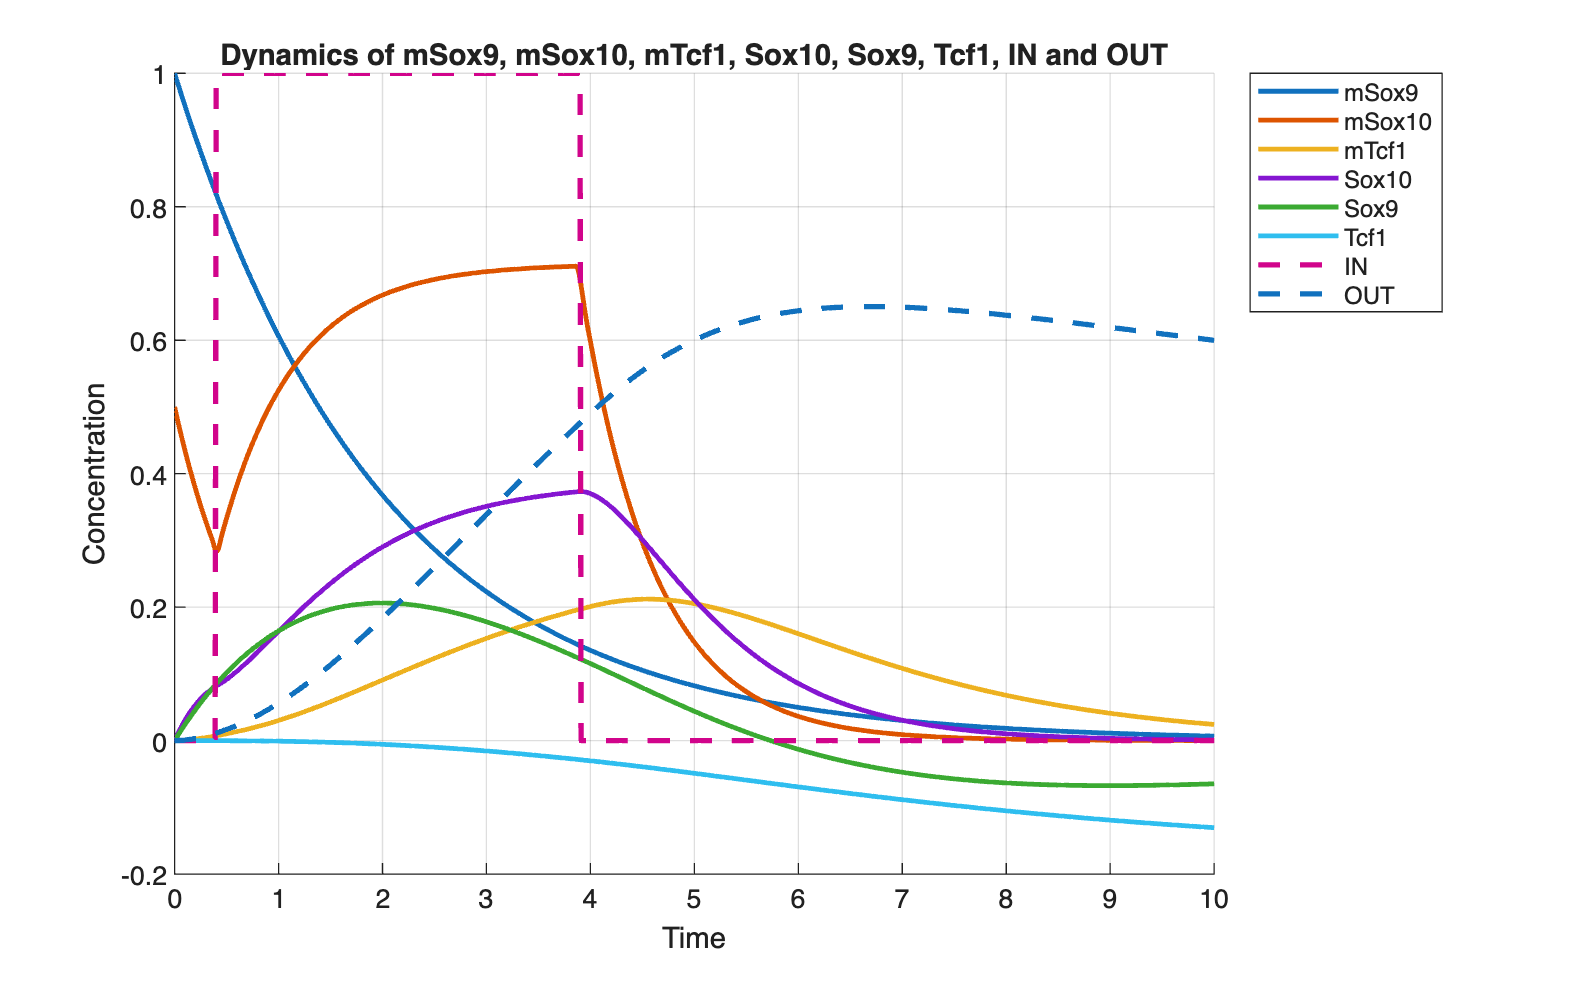

mSox10 = concentration(:,1);
Sox10  = concentration(:,2);
mSox9  = concentration(:,3);
Sox9   = concentration(:,4);
mTcf1  = concentration(:,5);
Tcf1   = concentration(:,6);
OUT    = concentration(:,10);

% Recompute IN(t) for plotting (same IN() you used in ode45)
IN_values = arrayfun(@(tt) input(tt), time);

% plot
figure('Units','normalized','OuterPosition',[0 0 1 1]);
hold on; grid on;

plot(time, mSox9,  'LineWidth',1.8);
plot(time, mSox10, 'LineWidth',1.8);
plot(time, mTcf1,  'LineWidth',1.8);
plot(time, Sox10,  'LineWidth',1.8);
plot(time, Sox9,   'LineWidth',1.8);
plot(time, Tcf1,   'LineWidth',1.8);

% Input and output signals
plot(time, IN_values, '--', 'LineWidth',2);
plot(time, OUT,       '--', 'LineWidth',2);

title('Dynamics of mSox9, mSox10, mTcf1, Sox10, Sox9, Tcf1, IN and OUT');
xlabel('Time');
ylabel('Concentration');

legend({'mSox9','mSox10','mTcf1','Sox10','Sox9','Tcf1','IN','OUT'}, ...
       'Location','bestoutside');

hold off;

%% Local functions
function concentrations = odeSystem(t, initialState, k, at, IN)

    mSox10 = initialState(1);
    Sox10 = initialState(2);
    mSox9 = initialState(3);
    Sox9 = initialState(4);
    mTcf1 = initialState(5);
    Tcf1 = initialState(6);
    miR155 = initialState(7);
    miR335 = initialState(8);
    miR338 = initialState(9);
    OUT = initialState(10);


    concentrations = [
        k(1) * IN - at(1) * mSox10 - k(2) * mSox10; % 1) mSox10 / Autoinduction acts as negative feedback via increased self-decay
        k(2) * mSox10 - 3 * k(3) * Sox10 - k(5) * (Sox10 + Sox10 * Tcf1) - k(8) * Sox10; % 2) Sox10
        -at(2) * mSox9 - k(4) * mSox9; % 3) mSox9 
        k(4) * mSox9 - k(5) * Sox9 - k(7) * miR338 - k(6) * miR335; % 4) Sox9 / is also consumed by interacting with the inhibitor miR335
        k(8) * Sox10 - at(3) * mTcf1 - k(4) * mTcf1; % 5) mTcf1
        k(4) * mTcf1 - k(5) * Tcf1 * Sox10 - k(7) * miR338 - k(6) * miR155; % 6) Tcf1
        k(3) * Sox10 - k(6) * miR155;  % 7) miR155 / inhibitors are consumed during the inhibition process
        k(3) * Sox10 - k(6) * miR335; % 8) miR335
        k(3) * Sox10 - 2 * k(7) * miR338; % 9) miR338
        k(5) * Sox10 + k(5) * Sox10 * Tcf1 + k(5) * Sox9; % 10) OUT (output)
        ];

end

function IN = input(t)
    % The input trigger IN is to be zero along the whole time of simulation except 
    % during the interval [0.4 , 3.9] where the value should be 1.
    if t >= 0.4 && t <= 3.9
        IN = 1;
    else
        IN = 0;
    end

end